clc; clear all; close all;
addpath("controllers")
addpath("trajectories")
addpath("odes")

Mass Spring Damper demo

There is a spring attached to the rotational system trying to hold it at 0

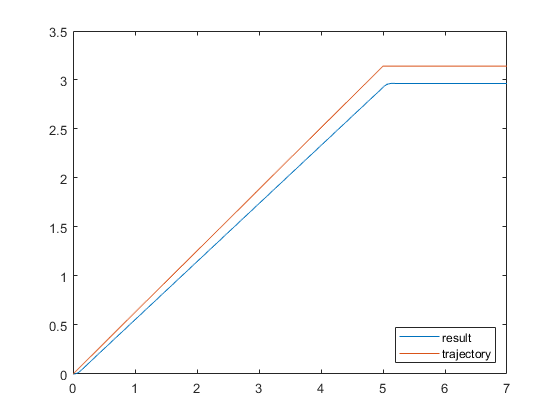

clc; clear all; close all;
% SETTING UP ODE
I = 1; % Kg*m^2
c = 20; % Nms/rad
k = 30; % Nm/rad
ode_fun = @(X) mass_spring_damper_ode(I, c, k, X);

% SETTING UP CONTROLLER
% Parameters for controller inputs
Kp = [500.0]; % Kp gain
Kd = [15.0];  % Kd gain
tau_fun = @(X,X_des) pd_controller(Kp,Kd,X,X_des);

% SETTING UP TRAJECTORY
% linear trajectory
x_start = 0;   x_end = pi; % rad
t_start = 0;    t_end = 5; % sec

traj_fun = @(t) linear_trajectory(x_start, x_end, t_start, t_end,t);

% SIM SETUP
x0 = [0 0];
tspan = [0 7];
[t,y] = ode45(@general_ode, tspan, x0, [], ode_fun, tau_fun, traj_fun);

% PLOT OUTPUT
for i = 1:length(t)
    traj(i,:) = traj_fun(t(i));
end

plot(t,y(:,1)); hold on;
plot(t,traj(:,1)); hold off;
legend('result','trajectory',"Location","southeast")

Single Pendulum demo

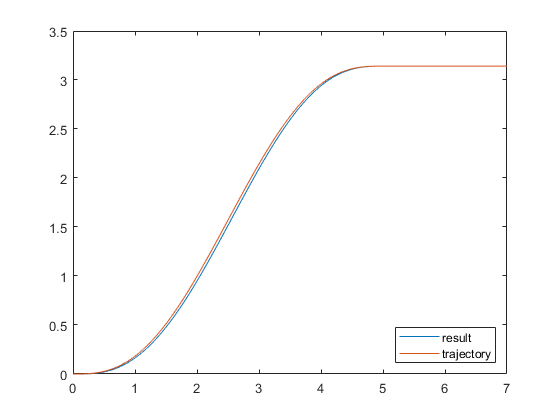

close all; clc; clear all;
%%%% SETTING UP ODE
l = 1.0;  % m
ode_fun = @(X) pendulum_ode_example(l, X);

% SETTING UP CONTROLLER
% Parameters for controller inputs
Kp = [500.0]; % Kp gain
Kd = [15.0];  % Kd gain
tau_fun = @(X,X_des) pd_controller(Kp,Kd,X,X_des);

% SETTING UP TRAJECTORY
% minimum jerk trajectory
x_start = 0;   x_end = pi; % rad
t_start = 0;    t_end = 5; % sec

traj_fun = @(t) mj_trajectory(x_start, x_end, t_start, t_end, t);

% SIM SETUP %%%%%%
x0 = [0 0];
tspan = [0 7];
[t,y] = ode45(@general_ode, tspan, x0, [], ode_fun, tau_fun, traj_fun);

% PLOT OUTPUT 
for i = 1:length(t)
    traj(i,:) = traj_fun(t(i));
end

plot(t,y(:,1)); hold on;
plot(t,traj(:,1)); hold off;
legend('result','trajectory',"Location","southeast")

%%%%%% END PLOT

Double Pendulum demo based on gohrbels last hw of both 508 and 501

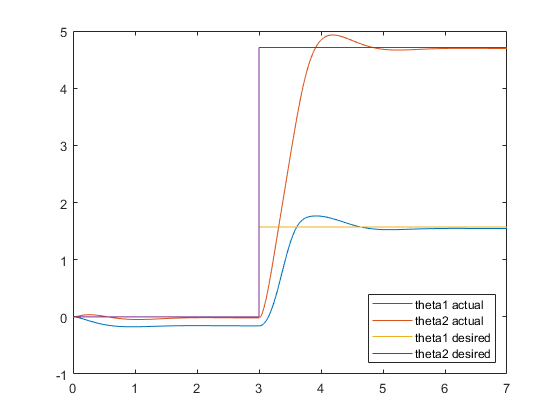

close all; clc; clear all;
%%%% ODE SETUP
m1  = 2;    % kg
m2  = 1;    % kg
I1  = 3;    % kg*m^2
I2  = 2;    % kg*m^2
lc1 = 0.75; % m
lc2 = 0.5;  % m
l1  = 1.5;  % m
l2  = 1.0;  % m

ode_fun = @(X) double_pendulum_ode_example(m1, m2, I1, I2, lc1, lc2, l1, l2, X);
%%%%%% END ODE %%%%%%

%%%%%% SETTING UP CONTROLLER %%%%%%
% Parameters for controller inputs
Kp = [200,0;0,40]; % Kp gains in diagonal matrix
Kd = [50,0;0,15]; % Kd gains in diagonal matrix
tau_fun = @(X,X_des) pd_controller(Kp,Kd,X,X_des);
%%%%%% END CONTROLLER %%%%%%

%%%%%% SETTING UP TRAJECTORY %%%%%%
% step trajectory
x_start = [0,0];   x_end = [pi/2,3*pi/2]; % rad
t_step = 3; % sec
traj_fun = @(t) step_trajectory(x_start, x_end, t_step, t);
%%%%%% END TRAJECTORY %%%%%%

%%%%%% SIM SETUP %%%%%%
x0 = [0 0 0 0];
tspan = [0 7];
[t,y] = ode45(@general_ode, tspan, x0, [], ode_fun, tau_fun, traj_fun);
%%%%%% END SIM %%%%%%

%%%%%% PLOT OUTPUT %%%%%%
for i = 1:length(t)
    traj(i,:) = traj_fun(t(i));
end

plot(t,y(:,1)); hold on;
plot(t,y(:,2)); hold on;
plot(t,traj(:,1)); hold on;
plot(t,traj(:,2)); hold off;
legend('theta1 actual','theta2 actual','theta1 desired','theta2 desired',"Location","southeast")

%%%%%% END PLOT